l_o = 1;
T_max = (.5*l_o)^2;

xpmax= 0.5*l_o;
ks = 3;
l = [0.0:0.01:1.5];
alpha = 1;

T_a = -alpha*((l-l_o).^2-T_max);
T_a(l<0.5) = 0;


xp = l - l_o

xp =    -1.0000   -0.9900   -0.9800   -0.9700   -0.9600   -0.9500   -0.9400   -0.9300   -0.9200   -0.9100   -0.9000   -0.8900   -0.8800   -0.8700   -0.8600   -0.8500   -0.8400   -0.8300   -0.8200   -0.8100   -0.8000   -0.7900   -0.7800   -0.7700   -0.7600   -0.7500   -0.7400   -0.7300   -0.7200   -0.7100   -0.7000   -0.6900   -0.6800   -0.6700   -0.6600   -0.6500   -0.6400   -0.6300   -0.6200   -0.6100   -0.6000   -0.5900   -0.5800   -0.5700   -0.5600   -0.5500   -0.5400   -0.5300   -0.5200   -0.5100


 
T_p = vpa(T_max/(exp(ks)-1))*(exp(ks*xp./xpmax)-1)

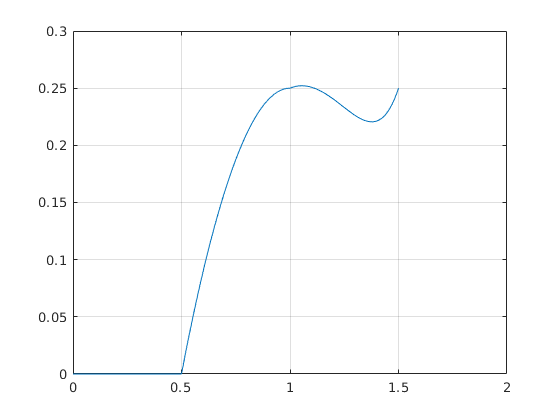

T_p(l<1.0) = 0;

T = T_a+T_p;
plot(l,T)


grid on
axis([0 2 0 0.3])


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

